
assets = flip(readmatrix('timeSeries.xlsx', 'Sheet', 'Problem 1 and 2', 'Range', 'C3:G1512'));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Task 1 a), Variance-Covariance Method
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

numColumns = size(assets, 2);
numRow = size(assets, 1);

w = 1 / numColumns;
w_matrix = repmat(w, numColumns,1);

returns = zeros(numRow-1,numColumns);

for row = 1: (numRow-1)
    for col = 1:(numColumns)
        returns(row,col) = (assets(row+1, col) - assets(row,col)) / assets(row,col);
    end
end

mu = mean(returns);
cov_matrix = cov(returns);
sigma = sqrt(transpose(w_matrix) * cov_matrix * w_matrix);
port_value = assets(numRow, 1:numColumns)*w_matrix;

VaR95 = (-mu + norminv(0.95)*sigma)*port_value *w_matrix

VaR95 = 5.7401

VaR99 = (-mu + norminv(0.99)*sigma)*port_value *w_matrix

VaR99 = 8.1705

The Value at Risk can be showed above.

L = - returns(numRow-1, 1:numColumns) * w_matrix * port_value

L = 0.1188


ES95 = mean(L(L > VaR95))

ES95 = NaN

ES99 = mean(L(L > VaR99))

ES99 = NaN

Since L is smaller than both VaR95 and VaR99 the answers to Expected Shortfall is not defined.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Task 1 b), Monte Carlo Simulation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%i)

log_returns = zeros(numRow-1,numColumns);

for row = 1: (numRow-1)
    for col = 1:(numColumns)
        log_returns(row,col) = log(assets(row+1, col)/ assets(row,col));
    end
end
% Optimization of GARCH with fmincon, without variance targeting

% Initial parameter guesses
initial_params = [0.1, 0.1, 0.8];

% Constraints: (0 <= omega, alpha, beta <= 1 and alpha + beta <= 1)
lb = [0, 0, 0];
ub = [1, 1, 1];
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = @(params) deal([], params(1) + params(2) - 1); % alpha + beta <= 1

% Optimization options
options = optimoptions('fmincon', 'Display', 'off');
parameters = zeros(3,numColumns);
variance_garch = zeros(numRow-1,numColumns);

for i = 1:numColumns
    [params_opt, neg_LL] = fmincon(@(params) garch_likelihood(params, log_returns(1:(numRow-1),i), "false"), initial_params, A, b, Aeq, beq, lb, ub, nonlcon, options);
    parameters(1:length(params_opt),i) = params_opt;
    [ll ,variance_GARCH] = garch_likelihood(params_opt, log_returns(1:(numRow-1),i), "false");
    variance_garch(1:numRow-1,i) = variance_GARCH;
end

parameters;
variance_garch;

%ii)
standard_returns = zeros(numRow-1,numColumns);

for col = 1:numColumns
    for row = 1:numRow-1
        standard_returns(row,col) = log_returns(row, col) / sqrt(variance_garch(row, col));
    end
end

standard_returns; %Standard returns equals the normally distirbuted residuals

U = zeros(numRow-1,numColumns);

for col = 1:numColumns
    U(1:numRow-1, col) = normcdf(standard_returns(1:numRow-1,col));
end

U;

[Rho_t, df] = copulafit('t', U);

%iii)
noOfSimulations = 1000;
rand_data = copularnd("t", Rho_t, df, noOfSimulations);

%iv)
residuals = norminv(rand_data);
rand_returns = residuals * transpose(sqrt(variance_garch(numRow-1,1:numColumns)));

rand_mu = mean(rand_returns);
rand_sigma= sqrt(var(rand_returns));

VaR95_rand = (-rand_mu + norminv(0.95)*sigma)*port_value

VaR95_rand = 6.0886

VaR99_rand = (-rand_mu + norminv(0.99)*sigma)*port_value

VaR99_rand = 8.5190


L_rand = - rand_returns(1:noOfSimulations,1)*port_value;

ES95_rand = mean(L_rand(L_rand > VaR95_rand))

ES95_rand = 15.1400

ES99_rand = mean(L_rand(L_rand > VaR99_rand))

ES99_rand = 16.7345

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Task 1 c), Extreme Value Theory
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%i) MLE

portfolio_returns = log_returns * w_matrix;
threshold = -quantile(portfolio_returns, 0.05)

threshold = 0.0284


excess_losses = -portfolio_returns(portfolio_returns < -threshold) - threshold; 

initial_params = [0.1, 1]; % Initial guesses for xi and beta
lb = [-Inf, 0]; % Lower bounds (beta > 0)
ub = [Inf, Inf]; % Upper bounds
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = [];
options = optimoptions('fmincon', 'Display', 'off');

[params_opt_EVT] = fmincon(@(params) EVT_log_likelihood(params, excess_losses), initial_params, A, b, Aeq, beq, lb, ub, nonlcon, options);
   
epsilon = params_opt_EVT(1)

epsilon = 0.3075

beta = params_opt_EVT(2)

beta = 0.0120

excess_rate = length(portfolio_returns)/length(excess_losses)

excess_rate = 20.1200


VaR_99_1d_EVT = (threshold + (beta/ epsilon) * (excess_rate * (1 - 0.99)^(epsilon) - 1))

VaR_99_1d_EVT = 0.1800

ES_99_1d_EVT = (VaR_99_1d_EVT + beta - epsilon * threshold) / (1 - epsilon)

ES_99_1d_EVT = 0.2647

The value of VaR and the constituent quantities can be shows in the display.

%ii) 500 observations

newdata = portfolio_returns(250:750);
threshold = -quantile(newdata, 0.05)

threshold = 0.0369

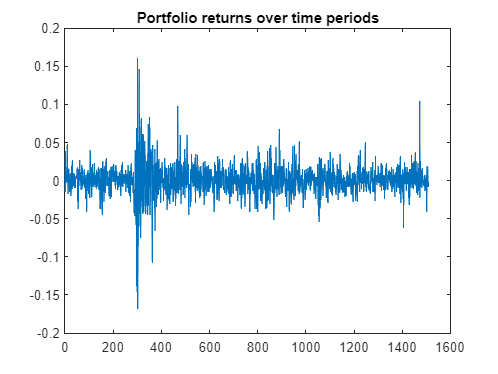


New_excess_losses = -newdata(newdata < -threshold) - threshold; 

figure;
plot(portfolio_returns) %Seem to be large fluctuations in returns from data points 250 to 750
title("Portfolio returns over time periods")


% data_points = portfolio_returns(250:750);

initial_params = [0.1, 1]; % Initial guesses for xi and beta
lb = [-Inf, 0]; % Lower bounds (beta > 0)
ub = [Inf, Inf]; % Upper bounds
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = [];
options = optimoptions('fmincon', 'Display', 'off');

[params_opt_EVT_2, neg_LL_EVT] = fmincon(@(params) EVT_log_likelihood(params, New_excess_losses), initial_params, A, b, Aeq, beq, lb, ub, nonlcon, options);
epsilon_500 = params_opt_EVT_2(1)

epsilon_500 = 0.3882

beta_500 = params_opt_EVT_2(2)

beta_500 = 0.0186

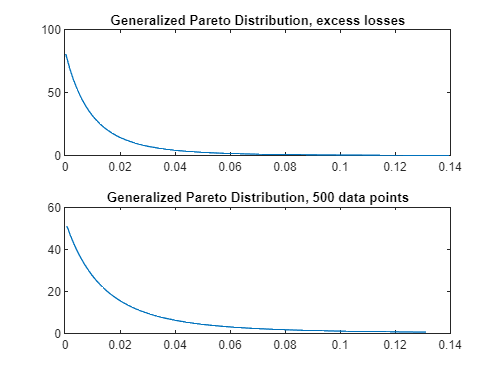

   %Plot the distribution functions

x1 = linspace(min(excess_losses), max(excess_losses), 100);
density1 = gpd_pdf(x1, epsilon, beta);

% Calculate the density for the 500 data points using the estimated parameters
x2 = linspace(min(New_excess_losses), max(New_excess_losses), 100);
density2 = gpd_pdf(x2, epsilon_500, beta_500);

figure;
subplot(2, 1, 1);
plot(x1, density1)
title('Generalized Pareto Distribution, excess losses')

subplot(2, 1, 2);
plot(x2, density2);
title('Generalized Pareto Distribution, 500 data points')


%VaR99 is normally distributed, VaR99_rand is Monte Carlo Simulated
Relative_VaR = VaR_99_1d_EVT/VaR99

Relative_VaR = 0.0220

The distribution functions shows that for VaR 99% the inital excess losses are larger for a lower percentage but it decreases faster than for the 500 data points. This may be due to the 500 data point interval being chosen as a volatile one.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Task 2 , Rolling Window Simulation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

window_size = 500;
N = length(log_returns);
confidence_levels = [0.95, 0.99];

portfolio_weights  = zeros(N, numColumns);
portfolio_weights(1:window_size+1 , 1:numColumns) = 1/numColumns;

sorted_returns = zeros(1, noOfSimulations);
VaR_RW = zeros(1, length(confidence_levels));
ES_RW = zeros(1, length(confidence_levels));
failures = zeros(1, length(confidence_levels));

port_return = zeros(N, 1);
hist_return = zeros(window_size,1);

for t = window_size+2:(N)
     port_return(t,1) = log_returns(t, :) * portfolio_weights(t-1,:)';
     %Update portfolio weights
    for i = 1:numColumns
        portfolio_weights(t,i) = portfolio_weights(t-1,i) * (1 + log_returns(t, i)) / (1+port_return(t,1));
    end
end

for t = window_size+2:(N)
    
    hist_return = log_returns(t-window_size:t-1,:) * portfolio_weights(t-1,:)';
    % Calculate VaR and ES
    sorted_returns = sort(hist_return);
    for cl = 1:length(confidence_levels)
        alpha = 1 - confidence_levels(cl);
        VaR_RW(t-window_size, cl) = -prctile(sorted_returns , alpha * 100);
        ES_RW(t-window_size, cl) = -mean(sorted_returns(sorted_returns <= -VaR_RW(t-window_size, cl)));
    end
    
    % Compare realized returns with VaR
    for cl = 1:length(confidence_levels)
        failures(t-window_size, cl) = port_return(t,1) < -VaR_RW(t-window_size, cl);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Task 2a, Two sided failure rate test
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Expected failure rate for 95% VaR
expected_failure_rate = 0.05;

% Count failures for 95% VaR
failures_95 = failures(:, 1); % First column corresponds to 95% VaR
observed_failure_rate = mean(failures_95);

% Perform binomial test, because the value can either be higher or lower
% than VaR
p_value = binocdf(sum(failures_95), N - window_size, expected_failure_rate);

% Two-sided test: Check if observed failure rate is significantly different from expected
if p_value < 0.025 || p_value > 0.975
    disp('Reject null hypothesis: Failure rate is significantly different from expected.');
else
    disp('Fail to reject null hypothesis: Failure rate is as expected.');
end

Reject null hypothesis: Failure rate is significantly different from expected.



disp(['Observed failure rate: ', num2str(observed_failure_rate)]);

Observed failure rate: 0.030723


disp(['Expected failure rate: ', num2str(expected_failure_rate)]);

Expected failure rate: 0.05


disp(['p-value: ', num2str(p_value)]);

p-value: 0.0018135


The p-value for the binomial cdf for the failure rate with 95% confidence is within the p-value interval. Therefore we reject the null hypothesis, in other words the failure rate is significantly different from the expected one. This implies that the VaR model is underestimating risk.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Task 2b, VaR Serial dependency (Christoffersen)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Binary sequence of VaR breaches
VaR_breaches = failures_95;

% Christoffersen test for serial independence
%1 = breach
%0 = no breach
n11 = sum(VaR_breaches(1:end-1) == 1 & VaR_breaches(2:end) == 1); %Number of times a breach is followed by another breach
n10 = sum(VaR_breaches(1:end-1) == 1 & VaR_breaches(2:end) == 0); %Number of times a breach is followed by no breach
n01 = sum(VaR_breaches(1:end-1) == 0 & VaR_breaches(2:end) == 1); %Number of times a no breach is followed by breach
n00 = sum(VaR_breaches(1:end-1) == 0 & VaR_breaches(2:end) == 0); %Number of times a no breach is followed by another no breach

% Likelihood ratio test statistic
% Measures Null model (first log) versus Alternative model (second log)
%Lnull is the likelihood under the null hypothesis (independent breaches),
%Lalternative is the likelihood of dependent breaches.
LR = -2 * log((1 - observed_failure_rate)^(n00 + n10) * observed_failure_rate^(n01 + n11)) + 2 * log((1 - n01 / (n00 + n01))^(n00) * (n01 / (n00 + n01))^(n01) * (1 - n11 / (n10 + n11))^(n10) * (n11 / (n10 + n11))^(n11))

LR = 3.0747


% From lecture 5
critical_value = 1.64

critical_value = 1.6400


% Compare test statistic to critical value
if LR > critical_value
    disp('Reject null hypothesis: VaR breaches are serially dependent.');
else
    disp('Fail to reject null hypothesis: VaR breaches are serially independent.');
end

Reject null hypothesis: VaR breaches are serially dependent.



disp(['Likelihood ratio test statistic: ', num2str(LR)]);

Likelihood ratio test statistic: 3.0747


disp(['Critical value: ', num2str(critical_value)]);

Critical value: 1.64


Since the Likelihood ratio is larger than the critical value for 95% confidence interval we reject the null hypothesis. In other word the VaR breaches are serially dependent.

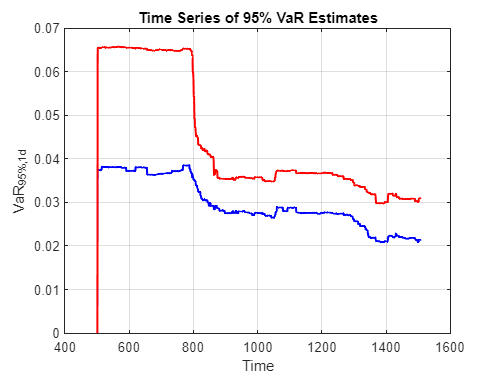

%Task 2, plots

% Plot time series of 95% VaR
figure;
plot(window_size+1:N, VaR_RW(1:N-window_size, 1), 'b', 'LineWidth', 1.5);
hold on;
plot(window_size+1:N, ES_RW(1:N-window_size, 1), 'r', 'LineWidth', 1.5); % Plot 95% ES
xlabel('Time');
ylabel('VaR_{95%,1d}');
title('Time Series of 95% VaR Estimates');
grid on;

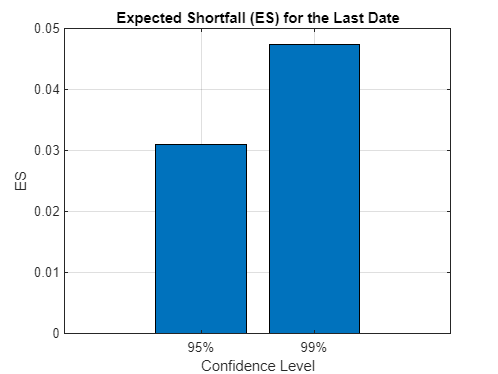


% Plot ES for the last date
figure;
bar(ES_RW(end, :));
xticklabels({'95%', '99%'});
xlabel('Confidence Level');
ylabel('ES');
title('Expected Shortfall (ES) for the Last Date');
grid on;

The VaR estimates fluctuate over time, indicating changes in the risk profile of the portfolio. Periods with higher VaR values suggest increased risk, while lower VaR values indicate reduced risk.

The Expected Shortfall tells us how bad the losses could be when they go beyond the VaR threshold. If the ES is high, it means that when losses do exceed the VaR, they are likely to be quite large. The ES at the 99% confidence level is higher than at the 95% level, which is expected since the 99% level captures more extreme outcomes.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Task 3a), Risk Factor
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Indexes = flip(readtable('timeSeries.xlsx', 'Sheet', 'Problem 3', 'Range', 'B3:E3429','VariableNamingRule', 'preserve'));

% Read the data as a table and preserve the original column headers
portfolio_data = readtable('timeSeries.xlsx', 'Sheet', 'Problem 3', 'Range', 'G3:L6', 'VariableNamingRule', 'preserve');

% Extract columns and convert to datetime
t = datetime(Indexes{end, 1}); % Convert the last row of the first column to datetime
T = datetime(portfolio_data{:, 2}); % Convert the second column to datetime

% Extract other variables as arrays
mid_iv = mean(portfolio_data{:, 4:5}, 2) / 100; % Mean of columns 4 and 5
K = portfolio_data{:, 1}; % Strike prices (numeric array)
Type = portfolio_data{:, 3}; % Option type (cell array of strings)
h = portfolio_data{:, 6}; % Other data (numeric array)
q = 0.05; % Dividend yield
risk_free_rates = Indexes{:, 4}/100;
S = Indexes{end, 2}; % Underlying asset price (numeric value)


option_prices = zeros(height(mid_iv),1);
Deltas = zeros(height(mid_iv), 1);
Vegas = zeros(height(mid_iv), 1);
Rhos = zeros(height(mid_iv), 1);

for i = 1:length(option_prices)
     [option_prices(i, 1), Deltas(i, 1), Vegas(i, 1), Rhos(i, 1)] = BlackScholes(S, K(i, 1), risk_free_rates(end, 1), q, t, T(i, 1), mid_iv(i, 1), Type(i, 1));
end

%Calculate changes

% Extract numeric data from the table
sp500_prices = Indexes{:, 2}; % Extract S&P 500 prices as a numeric array
vix_prices = Indexes{:, 3}/100; % Extract VIX prices as a numeric array
 % Extract risk-free rates as a numeric array

% Calculate changes in risk factors
log_returns_sp_500 = log(sp500_prices(2:end) ./ sp500_prices(1:end-1)); % Log returns for S&P 500
delta_VIX = vix_prices(2:end) - vix_prices(1:end-1); % Change in VIX
delta_r = risk_free_rates(2:end) - risk_free_rates(1:end-1); % Change in risk-free rate

RF = log_returns_sp_500(end,1)* transpose(h) * Deltas + delta_VIX(end,1) * transpose(h) * Vegas + delta_r(end,1) * transpose(h) * Rhos

RF = 3.9963e+05


risk_factor_changes = [log_returns_sp_500, delta_VIX, delta_r];

% Calculate the covariance matrix of risk factor changes
cov_matrix = cov(risk_factor_changes);

% Gradient vector (g) for the portfolio
g = [transpose(h) * Deltas; % Delta contribution
     transpose(h) * Vegas;  % Vega contribution
     transpose(h) * Rhos];  % Rho contribution

% Calculate portfolio variance
portfolio_variance = g' * cov_matrix * g;
portfolio_std = sqrt(portfolio_variance)

portfolio_std = 1.3176e+06


%Value at Risk
z_alpha = norminv(0.99); % For 99% confidence level
VaR_portfolio = z_alpha * sqrt(portfolio_variance)

VaR_portfolio = 3.0651e+06

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Task 3b), Marginal Contribution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Time_horizon = 1;
marginal_contributions = z_alpha * sqrt(Time_horizon) * (g' * cov_matrix * g * h) / sqrt(portfolio_variance)

marginal_contributions = 1.0e+10 *

    3.0651
    3.0651
    6.1302


**Functions:**

function [LL] = EVT_log_likelihood(params, data)

    epsilon = params(1);
    beta = params(2);

    T = length(data);
    loglikelihoods = zeros(T, 1);

    for t = 1:T
        loglikelihoods(t) = -log(beta) - (1 + (1 / epsilon)) * log(1 + (epsilon * data(t)) / beta);
    end
    LL = -sum(loglikelihoods);
    
end    

function [BS, Delta, Vega, Rho] = BlackScholes(S0, K, r, q, t, T, current_sigma, Type)
new_T = days252bus(t, T)/252;
S = S0*exp(-q * (new_T));
    
d1 = (log(S/K) + (r - q + (current_sigma^2)/2)*(new_T)) / (current_sigma*sqrt(new_T));
d2 = d1 - current_sigma*sqrt(new_T);

if Type == "Call"

    BS = S*exp(-q* (new_T))* normcdf(d1) - K*exp(-r*(new_T))*normcdf(d2);
    Delta = exp(-q * new_T) * normcdf(d1);
    Rho = K * new_T * exp(-r * new_T) * normcdf(d2);

elseif Type == "Put"

    BS =  K*exp(-r*(new_T))*normcdf(-d2) - S*exp(-q*(new_T))* normcdf(-d1);
    Delta = -exp(-q * new_T) * normcdf(-d1);
    Rho = -K * new_T * exp(- r * new_T) * normcdf(-d2);
end

    Vega = S * exp(-q * new_T) * normpdf(d1) * sqrt(new_T);

end

function y = gpd_pdf(x, epsilon, beta)
    y = (1 / beta) * (1 + epsilon * (x / beta)).^(-1/epsilon - 1);
end

function [LL, variance] = garch_likelihood(params, returns, is_fixed)
    
    if is_fixed == "true"
        omega = var(returns);
        alpha = params(1);
        beta = params(2);
    elseif is_fixed == "false"
        omega = params(1);
        alpha = params(2);
        beta = params(3);
    end
      
    % Initialize variables
    T = length(returns);
    variances = zeros(T,1);
    loglikelihoods = zeros(T,1);

    % Initial variance
    variances(1) = var(returns);
    % Calculate variances and log-likelihoods
    for t = 2:T
        variances(t) = omega * (1-alpha-beta) + alpha * returns(t-1)^2 + beta * variances(t-1);
        loglikelihoods(t) = -0.5 * (log(2*pi) + log(variances(t)) + returns(t)^2 / variances(t));
    end
    variance = variances(1:T,1);
    % Negative log-likelihood
    LL = -sum(loglikelihoods);
end
